# Use Custom `trackingKF` with Control Inputs

Specify a simulation time of 10 seconds with a time step of 1 second.

rng(2021) % For repeatable results
simulationTime = 20;
dt = 1;
tspan = 0:dt:simulationTime;
steps = length(tspan);

Specify the motion model as a 2-D constant velocity model with a state of [`x`; `vx`; `y`; `vy`]. The measurement is [`x`; `y`]. 

A1D = [1 dt; 0 1]; 
A = kron(eye(2),A1D) % State transiton model

A =      1     1     0     0
     0     1     0     0
     0     0     1     1
     0     0     0     1


H1D = [1 0];
H = kron(eye(2),H1D) % Measurement model 

H =      1     0     0     0
     0     0     1     0


sigma = 0.2;
R = sigma^2*eye(2); % Measurement noise covariance

Specify a control model matrix. 

B1D = [0; 1];
B = kron(eye(2),B1D) % Control model matrix

B =      0     0
     1     0
     0     0
     0     1


Assume the control inputs are sinusoidal on the velocity components, `vx` and `vy`. 

gain = 5;
Ux = gain*sin(tspan(2:end));
Uy = gain*cos(tspan(2:end));
U =[Ux; Uy]; % Control inputs

Assuming the true initial state is [`1 1 1 -1`], simulate the system to obtain true states and measurements.

initialState = [1 1 1 -1]'; % [m m/s m m/s]
trueStates = NaN(4,steps);
trueStates(:,1) = initialState;

for i=2:steps
    trueStates(:,i) = A*trueStates(:,i-1) + B*U(:,i-1);
end

measurements = H*trueStates + chol(R)*randn(2,steps);

Visualize the true trajectory and the measurements.

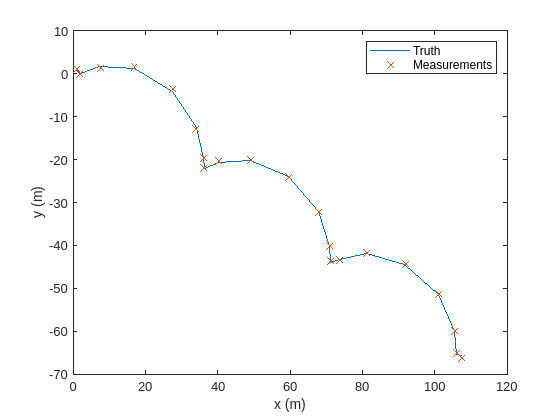

figure
plot(trueStates(1,:),trueStates(3,:),"DisplayName","Truth")
hold on
plot(measurements(1,:),measurements(2,:),"x","DisplayName","Measurements")
xlabel("x (m)")
ylabel("y (m)")
legend

Create a `trackingKF` filter with a custom motion model. Enable the control input by specifying the control model. Specify the initial state in the filter based on the first measurement.

initialFilterState = [measurements(1,1); 0; measurements(2,1); 0];
filter = trackingKF("MotionModel","Custom", ...
    "StateTransitionModel",A, ...
    "MeasurementModel",H, ...
    "ControlModel",B, ...
    "State",initialFilterState);

Estimate states by using the `predict` and `correct` object functions.

estimateStates = NaN(4,steps);
estimateStates(:,1) = initialFilterState;
for i = 2:steps
    predict(filter,U(:,i-1));
    estimateStates(:,i) = correct(filter,measurements(:,i));
end

Visualize the state estimates.

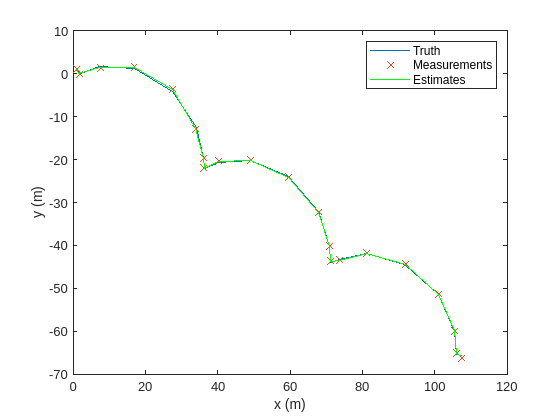

plot(estimateStates(1,:),estimateStates(3,:),"g","DisplayName","Estimates");

*Copyright 2021 The MathWorks, Inc.*